# 资产组合的有效前沿

本节在$E-\sigma \;$图像上作延拓, 了解如何简便地画出该图像. 并且从非线性规划角度重新思考这个问题.

使用第2节中的数据.

clear
close all
load price_2m_50stocks.mat

期望收益率.

rtn = diff(log(price));
rtnM = prod(1+rtn)'-1;  % 2个月总收益率

rtnM =     0.0143
   -0.0010
   -0.0583
   -0.0422
   -0.0758
   -0.0281
   -0.0009
   -0.0433
    0.0273
    0.0141


协方差矩阵.

sigma = cov(rtn);

风险边界上描点的数量.

n = 100;

计算投资组合的有效前沿.

p = Portfolio;
p = setAssetMoments(p, rtnM, sigma);
p = setDefaultConstraints(p);

计算风险边界上n个点的单个资产权重.

PortWts = estimateFrontier(p, n)

PortWts =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0    0.0196    0.0440    0.0684    0.0928    0.1094    0.1251    0.1354    0.1446    0.1514    0.1537    0.1560    0.1582    0.1605    0.1628    0.1651    0.1673    0.1696    0.1719    0.1741    0.1761    0.1756    0.1709    0.1630    0.1516    0.1393    0.1270    0.1146    0.1023    0.0897    0.0766    0.0635    0.0503    0.0394    0.0286    0.0178    0.0071         0         0         

计算风险边界上n个点对应的风险和回报.

[PortRisk, PortReturn] = estimatePortMoments(p, PortWts);
disp([PortRisk, PortReturn, [1:n]']);

    0.0055   -0.0187    1.0000
    0.0055   -0.0153    2.0000
    0.0055   -0.0118    3.0000
    0.0055   -0.0084    4.0000
    0.0055   -0.0050    5.0000
    0.0055   -0.0015    6.0000
    0.0056    0.0019    7.0000
    0.0056    0.0054    8.0000
    0.0057    0.0088    9.0000
    0.0057    0.0122   10.0000
    0.0058    0.0157   11.0000
    0.0058    0.0191   12.0000
    0.0059    0.0226   13.0000
    0.0060    0.0260   14.0000
    0.0060    0.0294   15.0000
    0.0061    0.0329   16.0000
    0.0062    0.0363   17.0000
    0.0063    0.0398   18.0000
    0.0064    0.0432   19.0000
    0.0065    0.0467   20.0000
    0.0066    0.0501   21.0000
    0.0067    0.0535   22.0000
    0.0068    0.0570   23.0000
    0.0069    0.0604   24.0000
    0.0070    0.0639   25.0000
    0.0071    0.0673   26.0000
    0.0072    0.0707   27.0000
    0.0073    0.0742   28.0000
    0.0075    0.0776   29.0000
    0.0076    0.0811   30.0000
    0.0077    0.0845   31.0000
    0.0078    0.0879   32.0000
    0.00

绘制有效前沿.

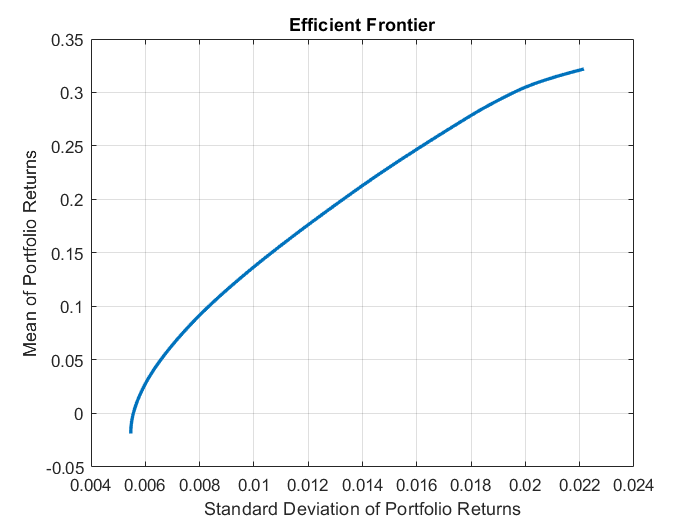

plotFrontier(p, n)